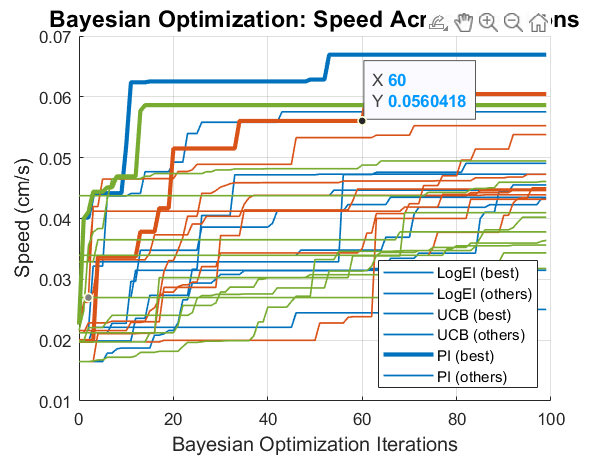

acqs = {'LogEI', 'UCB', 'PI'};  % Acquisition functions
colors = {[0, 0.447, 0.741], [0.850, 0.325, 0.098], [0.466, 0.674, 0.188]};  % blue, orange, green
num_sets = 10;
num_iters = 100;

figure;
hold on;

for a = 1:length(acqs)
    acq = acqs{a};
    all_data = zeros(num_iters, num_sets);

    % Load all 10 CSVs and extract the 'best_speed' column
    for n = 1:num_sets
        filename = sprintf('%s_combined_set_%d.csv', acq, n);
        T = readtable(filename);
        
        % Ensure best_speed exists and is column vector
        if ismember('best_speed', T.Properties.VariableNames)
            all_data(:, n) = T.best_speed(1:num_iters);
        else
            error('Missing column "best_speed" in %s', filename);
        end
    end

    % Determine which set had the highest final best_speed
    [~, best_idx] = max(all_data(end, :));

    % Plot all, highlight best
    for n = 1:num_sets
        alpha = 0.5;
        lw = 1;
        if n == best_idx
            alpha = 1.0;
            lw = 2.5;
        end
        plot(0:num_iters-1, all_data(:, n), 'Color', [colors{a}, alpha], 'LineWidth', lw);
    end
end

xlabel('Bayesian Optimization Iterations', 'FontSize', 12);
ylabel('Speed (cm/s)', 'FontSize', 12);
legend({'LogEI (best)', 'LogEI (others)', ...
        'UCB (best)', 'UCB (others)', ...
        'PI (best)', 'PI (others)'}, 'Location', 'southeast');
title('Bayesian Optimization: Speed Across Iterations', 'FontSize', 14);
grid on;

% Save the figure
saveas(gcf, 'bo_speed_vs_iterations.png');
saveas(gcf, 'bo_speed_vs_iterations.svg');

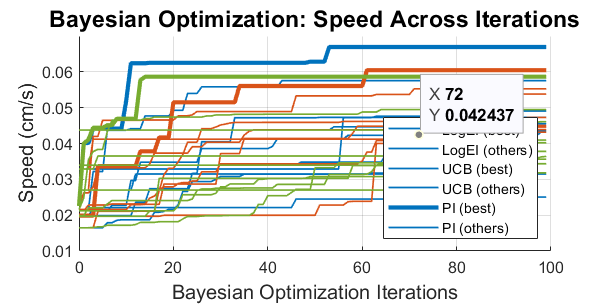

acqs = {'LogEI', 'UCB', 'PI'};  % Acquisition functions
base_colors = {[0, 0.447, 0.741], [0.850, 0.325, 0.098], [0.466, 0.674, 0.188]};
num_sets = 10;
num_iters = 100;

%% =================== Plot 1: Highlight Best Per Acquisition ===================
figure('Name', 'Best Highlighted', 'Position', [100, 100, 1000, 500]);
hold on;

for a = 1:length(acqs)
    acq = acqs{a};
    all_data = zeros(num_iters, num_sets);

    for n = 1:num_sets
        filename = sprintf('%s_combined_set_%d.csv', acq, n);
        T = readtable(filename);
        if ismember('best_speed', T.Properties.VariableNames)
            all_data(:, n) = T.best_speed(1:num_iters);
        else
            error('Missing column "best_speed" in %s', filename);
        end
    end

    [~, best_idx] = max(all_data(end, :));

    for n = 1:num_sets
        alpha = 0.5;
        lw = 1;
        if n == best_idx
            alpha = 1.0;
            lw = 2.5;
        end
        plot(0:num_iters-1, all_data(:, n), 'Color', [base_colors{a}, alpha], 'LineWidth', lw);
    end
end

xlabel('Bayesian Optimization Iterations', 'FontSize', 12);
ylabel('Speed (cm/s)', 'FontSize', 12);
legend({'LogEI (best)', 'LogEI (others)', ...
        'UCB (best)', 'UCB (others)', ...
        'PI (best)', 'PI (others)'}, 'Location', 'southeast');
title('Bayesian Optimization: Speed Across Iterations', 'FontSize', 14);
grid on;

saveas(gcf, 'bo_speed_vs_iterations.png');
saveas(gcf, 'bo_speed_vs_iterations.svg');

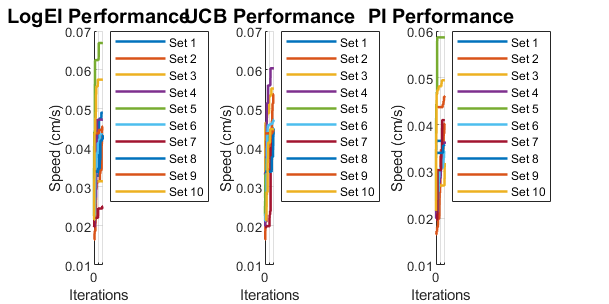


%% =================== Plot 2: Subplots for Each Acquisition Function ===================
figure('Name', 'Subplots Per Acquisition Function', 'Position', [100, 100, 1200, 600]);

for a = 1:length(acqs)
    acq = acqs{a};
    cmap = lines(num_sets);  % Distinct color for each dataset

    subplot(1, 3, a);
    hold on;

    for n = 1:num_sets
        filename = sprintf('%s_combined_set_%d.csv', acq, n);
        T = readtable(filename);
        plot(0:num_iters-1, T.best_speed(1:num_iters), 'Color', cmap(n,:), 'LineWidth', 1.5);
    end

    title(sprintf('%s Performance', acq), 'FontSize', 12);
    xlabel('Iterations');
    ylabel('Speed (cm/s)');
    legend(arrayfun(@(x) sprintf('Set %d', x), 1:num_sets, 'UniformOutput', false), ...
           'Location', 'bestoutside');
    grid on;
end

saveas(gcf, 'bo_acq_subplots.png');
saveas(gcf, 'bo_acq_subplots.svg');

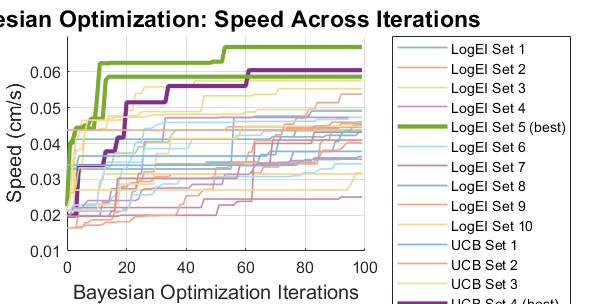

acqs = {'LogEI', 'UCB', 'PI'};  % Acquisition functions
num_sets = 10;
num_iters = 100;
cmap_all = lines(num_sets);  % 10 distinct colors

%% ========== Plot 1: Unified plot with correct legend ==========

figure('Name', 'Best Highlighted (Corrected Legend)', 'Position', [100, 100, 1000, 500]);
hold on;

legend_entries = {};
line_handles = [];

for a = 1:length(acqs)
    acq = acqs{a};
    all_data = zeros(num_iters, num_sets);

    for n = 1:num_sets
        filename = sprintf('%s_combined_set_%d.csv', acq, n);
        T = readtable(filename);
        all_data(:, n) = T.best_speed(1:num_iters);
    end

    [~, best_idx] = max(all_data(end, :));

    for n = 1:num_sets
        alpha = 0.5; lw = 1;
        if n == best_idx
            alpha = 1.0; lw = 2.5;
        end
        h = plot(0:num_iters-1, all_data(:, n), ...
                 'Color', [cmap_all(n,:) * alpha + (1 - alpha)], ...
                 'LineWidth', lw);
        line_handles(end+1) = h; %#ok<SAGROW>
        legend_entries{end+1} = sprintf('%s Set %d%s', acq, n, ...
            ternary(n == best_idx, ' (best)', '')); %#ok<SAGROW>
    end
end

xlabel('Bayesian Optimization Iterations', 'FontSize', 12);
ylabel('Speed (cm/s)', 'FontSize', 12);
title('Bayesian Optimization: Speed Across Iterations', 'FontSize', 14);
legend(line_handles, legend_entries, 'Location', 'eastoutside');
grid on;
ylim auto;

saveas(gcf, 'bo_speed_all_corrected_legend.png');
saveas(gcf, 'bo_speed_all_corrected_legend.svg');

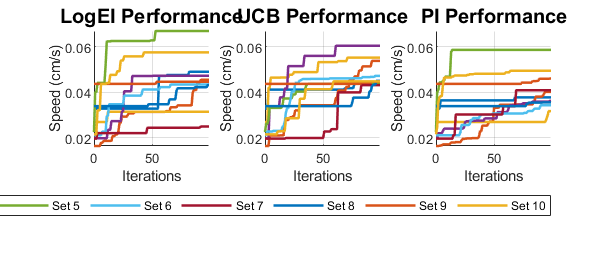


%% ========== Plot 2: Subplots with consistent axes ==========

% Get global min and max for consistent axis limits
global_min = inf;
global_max = -inf;

% Pre-load all speeds for each acq to reuse
all_speeds = cell(1, length(acqs));

for a = 1:length(acqs)
    acq = acqs{a};
    temp_data = zeros(num_iters, num_sets);
    for n = 1:num_sets
        filename = sprintf('%s_combined_set_%d.csv', acq, n);
        T = readtable(filename);
        temp_data(:, n) = T.best_speed(1:num_iters);
        global_min = min(global_min, min(temp_data(:, n)));
        global_max = max(global_max, max(temp_data(:, n)));
    end
    all_speeds{a} = temp_data;
end

% Plot subplots
figure('Name', 'Subplots Per Acquisition Function', 'Position', [100, 100, 1200, 500]);

for a = 1:length(acqs)
    subplot(1, 3, a);
    hold on;

    for n = 1:num_sets
        plot(0:num_iters-1, all_speeds{a}(:, n), ...
             'Color', cmap_all(n,:), 'LineWidth', 1.5);
    end

    title(sprintf('%s Performance', acqs{a}), 'FontSize', 12);
    xlabel('Iterations');
    ylabel('Speed (cm/s)');
    legend(arrayfun(@(x) sprintf('Set %d', x), 1:num_sets, 'UniformOutput', false), ...
           'Location', 'southoutside', 'Orientation', 'horizontal');
    xlim([0, num_iters-1]);
    ylim([global_min, global_max]);
    grid on;
end

saveas(gcf, 'bo_speed_subplots_uniform_axes.png');
saveas(gcf, 'bo_speed_subplots_uniform_axes.svg');


%% ========== Helper Function ========

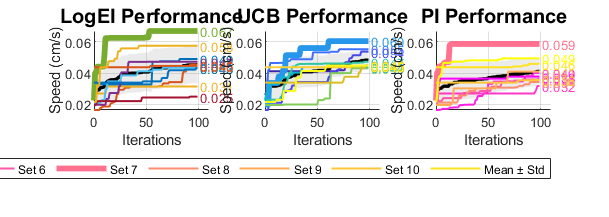

acqs = {'LogEI', 'UCB', 'PI'};
colormaps = {@(n) lines(n), @(n) parula(n), @(n) spring(n)};
num_sets = 10;
num_iters = 100;

% Global limits
global_min = inf;
global_max = -inf;

all_speeds = cell(1, length(acqs));
best_indices = zeros(1, length(acqs));

% Load all data
for a = 1:length(acqs)
    acq = acqs{a};
    speeds = zeros(num_iters, num_sets);
    
    for n = 1:num_sets
        filename = sprintf('%s_combined_set_%d.csv', acq, n);
        T = readtable(filename);
        speeds(:, n) = T.best_speed(1:num_iters);
        global_min = min(global_min, min(speeds(:, n)));
        global_max = max(global_max, max(speeds(:, n)));
    end
    
    all_speeds{a} = speeds;
    [~, best_indices(a)] = max(speeds(end, :));
end

% Plotting
figure('Name', 'Subplots + Mean/Std + Final Annotations', 'Position', [100, 100, 1400, 500]);

for a = 1:length(acqs)
    subplot(1, 3, a);
    hold on;
    
    cmap = colormaps{a}(num_sets);
    speeds = all_speeds{a};
    best_idx = best_indices(a);
    
    % Mean and std
    mean_speed = mean(speeds, 2);
    std_speed = std(speeds, 0, 2);

    % Shaded area (std)
    fill([0:num_iters-1, fliplr(0:num_iters-1)], ...
         [mean_speed' + std_speed', fliplr(mean_speed' - std_speed')], ...
         [0.6 0.6 0.6], 'FaceAlpha', 0.2, 'EdgeColor', 'none');

    % Mean line
    plot(0:num_iters-1, mean_speed, 'k-', 'LineWidth', 2);

    % Individual lines
    for n = 1:num_sets
        lw = 1.2; style = '-';
        if n == best_idx
            lw = 3.5;
        end
        h = plot(0:num_iters-1, speeds(:, n), 'Color', cmap(n, :), 'LineWidth', lw, 'LineStyle', style);
        
        % Final value annotation
        y_val = speeds(end, n);
        text(num_iters + 1, y_val, sprintf('%.3f', y_val), ...
             'FontSize', 8, 'Color', cmap(n, :), 'HorizontalAlignment', 'left');
    end

    title(sprintf('%s Performance', acqs{a}), 'FontSize', 12);
    xlabel('Iterations');
    ylabel('Speed (cm/s)');
    legend([arrayfun(@(x) sprintf('Set %d%s', x, ...
        ternary(x == best_idx, ' (best)', '')), 1:num_sets, 'UniformOutput', false), ...
        'Mean ± Std'], 'Location', 'southoutside', 'Orientation', 'horizontal');

    xlim([0, num_iters + 10]);  % Extra space for annotation
    ylim([global_min, global_max]);
    grid on;
end

% Save output
saveas(gcf, 'bo_subplots_mean_std_annotated.png');
saveas(gcf, 'bo_subplots_mean_std_annotated.svg');

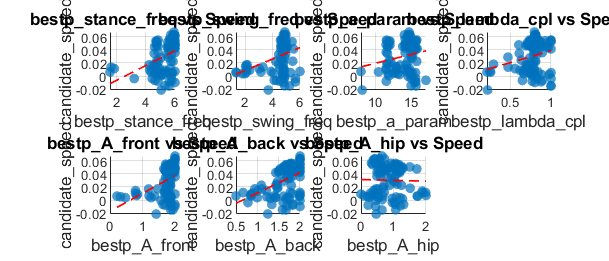

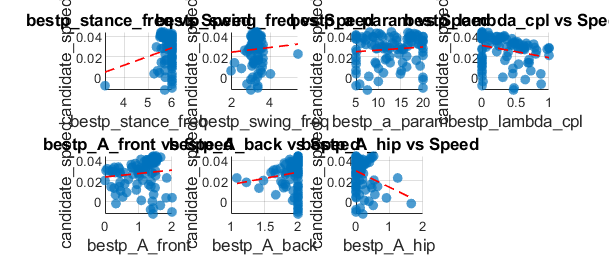

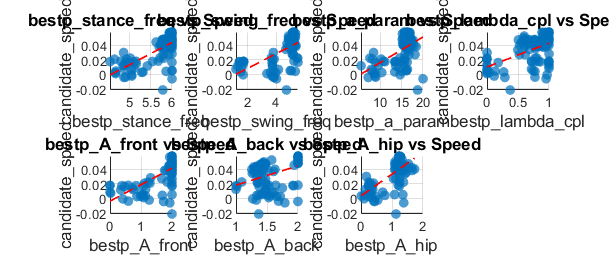

acqs = {'LogEI', 'UCB', 'PI'};
params = {'bestp_stance_freq', 'bestp_swing_freq', 'bestp_a_param', ...
          'bestp_lambda_cpl', 'bestp_A_front', 'bestp_A_back', 'bestp_A_hip'};
num_params = length(params);

for a = 1:length(acqs)
    acq = acqs{a};
    filename = sprintf('%s_combined_set_5.csv', acq);
    T = readtable(filename);

    figure('Name', sprintf('%s - Set 5 Param Relationships', acq), ...
           'Position', [100, 100, 1400, 600]);
    
    for i = 1:num_params
        subplot(2, 4, i);
        scatter(T.(params{i}), T.candidate_speed, 35, 'filled', ...
                'MarkerFaceAlpha', 0.7);
        xlabel(strrep(params{i}, '_', '\_'), 'FontSize', 10);
        ylabel('candidate\_speed', 'FontSize', 10);
        title(sprintf('%s vs Speed', strrep(params{i}, '_', '\_')), 'FontSize', 10);
        grid on;
        
        % Optional: Linear fit
        hold on;
        x = T.(params{i});
        y = T.candidate_speed;
        p = polyfit(x, y, 1);
        x_fit = linspace(min(x), max(x), 100);
        y_fit = polyval(p, x_fit);
        plot(x_fit, y_fit, 'r--', 'LineWidth', 1);
    end

    % Save figure
    saveas(gcf, sprintf('%s_param_vs_speed_set5.png', acq));
end

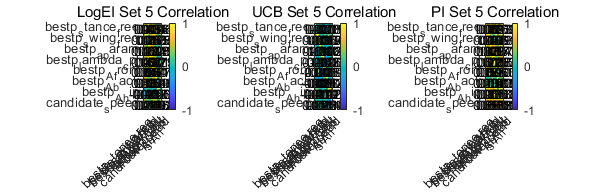

acqs   = {'LogEI','UCB','PI'};
params = {'bestp_stance_freq','bestp_swing_freq','bestp_a_param', ...
          'bestp_lambda_cpl','bestp_A_front','bestp_A_back', ...
          'bestp_A_hip','candidate_speed'};
N = numel(params);

figure('Position',[100 100 1400 450]);
for a = 1:3
    % 1) load
    T = readtable(sprintf('%s_combined_set_5.csv',acqs{a}));
    M = table2array( T(:,params) );
    C = corrcoef(M,'Rows','complete');

    % 2) subplot + image
    ax = subplot(1,3,a);
    imagesc(C);
    colormap(ax,parula);
    caxis([-1 1]);
    colorbar;

    % 3) ticks & labels
    ax.XTick = 1:N;
    ax.YTick = 1:N;
    ax.XTickLabel = params;
    ax.YTickLabel = params;
    ax.XTickLabelRotation = 45;
    ax.TickLength = [0 0];
    title(sprintf('%s Set 5 Correlation',acqs{a}),'FontWeight','normal');

    % 4) annotate each cell
    for i = 1:N
      for j = 1:N
        text(j,i,sprintf('%.2f',C(i,j)),...
             'HorizontalAlignment','center', ...
             'FontSize',8, ...
             'Color','k');
      end
    end
end

% Save once for the entire figure
saveas(gcf,'all_acq_set5_corr_heatmaps.png');




% Ternary helper function

function out = ternary(cond, true_val, false_val)
    if cond
        out = true_val;
    else
        out = false_val;
    end
end

